clear all;
close all;
addpath("compute_descriptors/");

rng("shuffle", "twister");

TRAIN = false;
SIFT = false;

warning('off')

annotationsFileName = "UNO-GT.json";

cocoTrainData = jsondecode(fileread(annotationsFileName));
images = struct2table(cocoTrainData.images);
imag = images.id;
annotations = struct2table(cocoTrainData.annotations);
categories = struct2table(cocoTrainData.categories);

if(TRAIN)
    cv = cvpartition(size(imag,1), 'HoldOut', 0.2);

    annotationsTrain = annotations(ismember(annotations.image_id, imag(cv.training(1))) ,:);
    imagesTrain = images(ismember(images.id, imag(cv.training(1))) ,:);
    
    [cardsTrain, labelsTrain] = readlist(imagesTrain, annotationsTrain, categories);
    
    annotationsTest = annotations(ismember(annotations.image_id, imag(cv.test(1))) ,:);
    imagesTest = images(ismember(images.id, imag(cv.test(1))) ,:);
end

if(TRAIN) 
    create_training_descriptor_files(cardsTrain, labelsTrain);
    
    load("data_training.mat");
    
    [featuresCards, labelsCards, TCards] = ClassificatorCards();
    
    if(SIFT)
        load("BagOfFeatures.mat");
        
        C = fitcknn(featuresCards, labelsCards, "Distance", "cosine", ...
            'Exponent', [], ...
            'NumNeighbors', 10, ...
            'DistanceWeight', 'Equal', ...
            'Standardize', true);
    else
        template = templateTree(...
                        'MaxNumSplits', 300, ...
                        'NumVariablesToSample', 'all');
        C = fitcensemble(...
                        featuresCards, ...
                        labelsCards, ...
                        'Method', 'Bag', ...
                        'NumLearningCycles', 30, ...
                        'Learners', template);
    end

    [featuresColor, labelsColor, TColor] = ClassificatorColors();
    
    CC = fitcknn(featuresColor, labelsColor, "Distance", "cosine", ...
            'Exponent', [], ...
            'NumNeighbors', 10, ...
            'DistanceWeight', 'Equal', ...
            'Standardize', true);
    
    save("models.mat", "C", "CC", "imagesTrain", "annotationsTrain", "imagesTest", "annotationsTest");
else
    load("data_training.mat");
    load("models.mat");
end

ans = struct with fields:
      cm_raw: [10×10 double]
          cm: [10×10 double]
      labels: [10×1 string]
    accuracy: 0.7778


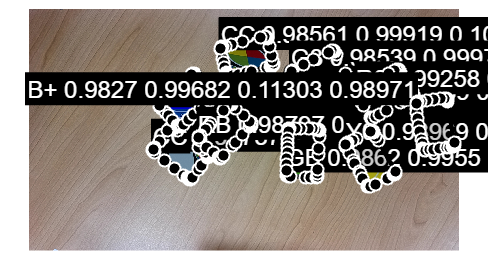

ans = struct with fields:
      cm_raw: [11×11 double]
          cm: [11×11 double]
      labels: [11×1 string]
    accuracy: 0.9091


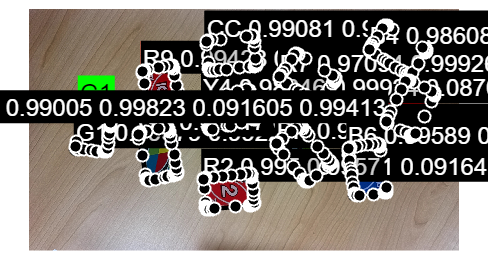

ans = struct with fields:
      cm_raw: [14×14 double]
          cm: [14×14 double]
      labels: [14×1 string]
    accuracy: 0.5000


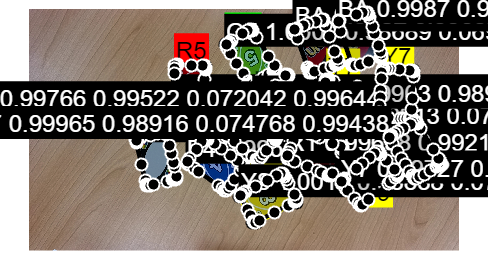

ans = struct with fields:
      cm_raw: [10×10 double]
          cm: [10×10 double]
      labels: [10×1 string]
    accuracy: 0.8889


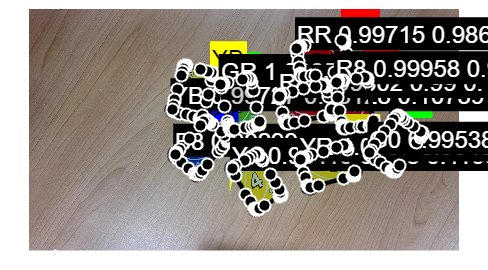

ans = struct with fields:
      cm_raw: [14×14 double]
          cm: [14×14 double]
      labels: [14×1 string]
    accuracy: 0.7143


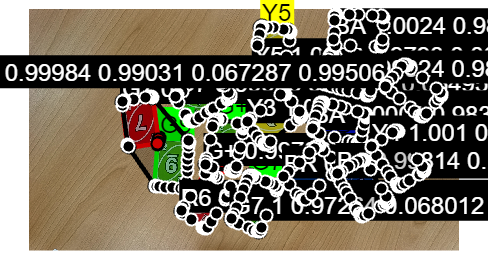

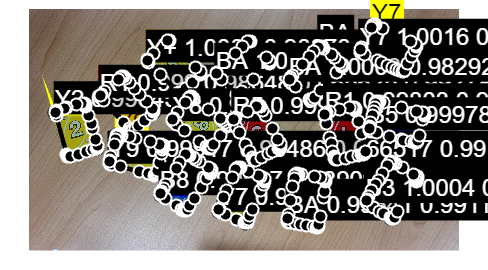

ans = struct with fields:
      cm_raw: [12×12 double]
          cm: [12×12 double]
      labels: [12×1 string]
    accuracy: 0.9333


for k1 = 1:min(height(imagesTest))
    name = imagesTest(k1, "path");
    im = imread(name{1,1}{1});

    id = imagesTest(k1, "id");
    id = id{1,1};  
    
    ann = annotations(annotations.image_id == id, :);

    hold off;
    figure(k1);
    imshow(im); 
    hold on;

    polygons = zeros([size(im, 1), size(im, 2), height(ann)]);
    catpol = strings([1 height(ann)]);
    
    for row = 1:height(ann)
        catto = categories(categories.id == ann{row,3}, :);
        color = sscanf(catto{1,4}{1}(2:end),'%2x%2x%2x',[1 3])/255;

        p = ann{row,4};
        polygon = p{1,1};

        BW = zeros(size(im, 1), size(im, 2)); 
      
        for Npol = 1:size(polygon, 1)  %% per poligoni spezzati
            pol = reshape(polygon(Npol, :), [2,size(polygon(Npol, :), 2)/2])';
           
            BW = BW | poly2mask(pol(:,1), pol(:,2), size(im, 1), size(im, 2));                           
           
            drawpolygon("Position", pol, "Tag", string(catto{1,1}), "Label", catto{1,2}{1}, "Color", color);  %% piu' poligoni con lo stesso tag per poligoni spezzati
           
        end
        
        polygons(:,:,row) = BW;
        catpol(row) = catto{1,2}{1};

    end

    BW = Binarize(im);

    B = bwboundaries(BW);
        
    conf = [];
    for row = 1:height(B)
        [P,av] = convhull(B{row,1}, 'Simplify',true);

        %poly = reshape(P, [2,size(P, 1)/2])';

        BWCard = poly2mask(B{row,1}(P,2), B{row,1}(P,1), size(im, 1), size(im, 2));

        res = immultiply(im, cat(3, BW, BW, BW)); 

        [r, c] = find(BWCard);
        row1 = min(r);
        row2 = max(r);
        col1 = min(c);
        col2 = max(c);
        croppedIm = res(row1:row2, col1:col2, :);

        croppedIm = imresize(croppedIm, 1);

        angle = horizon(BWCard(row1:row2, col1:col2, :), 0.1, 'hough');
        rota = imrotate(croppedIm, -angle, 'bicubic');
        prota = rgb2gray(rota) > 40;
        prota = imfill(prota, "holes");

        [r, c] = find(prota);
        row1 = min(r);
        row2 = max(r);
        col1 = min(c);
        col2 = max(c);

        rota = rota(row1:row2, col1:col2, :);

        if(size(rota,2) > size(rota,1))
            rota = rot90(rota);
        end

        [lbp, cedd, qhist, si, su, ka, eul, areas, nconn, perimeter, orientation, convexArea, circularity, huMoments] = create_descriptor(rota);

        aaa = [areas, eul, perimeter, orientation, convexArea, circularity, nconn, huMoments];
        aaaC = [qhist];

        if(SIFT)
            [vsi, vsu, vka] = calculate_features(si, su, ka, nlab, Cs, Cu, Ck);
            aaa = [aaa, vsi];
        end

        label = predict(C,aaa);
        if(label == "F")
            label = "PF";
        elseif(label == "C")
            label = "CC";
        elseif(label == "A")
            label = "BA";
        elseif(label == "N")
            label = "UN";
        else
            labelC = predict(CC, aaaC);
            label = strcat(labelC, label);
        end

        maxar = 0;
        maxx = 0;

        for po = 1:height(ann)
            intersection = BWCard & polygons(:,:,po);
            
            ar = bwarea(intersection);
            ar = sum(ar);

            if(ar > maxar)
                maxar = ar;
                maxx = po;
            end
        end
 
        intersection = BW & polygons(:,:,maxx);
        union = BW | polygons(:,:,maxx);

        arI = bwarea(intersection);
        arI = sum(arI);

        arU = bwarea(union);
        arU = sum(arU);

        ar = bwarea(BWCard);
        ar = sum(ar);

        arO = bwarea(polygons(:,:,maxx));
        arO = sum(arO);

        precision = arI / ar;
        IoU = arI / arU;
        recall = arI / arO;

        F1 = 2*(precision*recall)/(precision + recall);
        
        lab = label{1} + " " + string(precision) + " " + string(recall) + " " + string(IoU) + " " + string(F1);

        drawpolygon("Position", [B{row,1}(P,2), B{row,1}(P,1)], "Label", lab , "Color", "black");

        conf = cat(1, conf, [catpol(maxx), label{1}]);
    end
    confmat(conf(:,1), conf(:,2))
end